# 清空环境

clc
clear

## 遗传算法参数

% 值得注意的是，当前的实现所计算出的结果，比书上的更优
maxgen = 40;                         % 进化代数
sizepop = 100;                       % 种群规模
pcross = 0.6;                        % 交叉概率
pmutation = 0.01;                    % 变异概率
lenchrom = [1 1 1 1 1];              % 变量字串长度
bound = [0 0.9*pi; 
       0 0.9*pi;
       0 0.9*pi;
       0 0.9*pi;
       0 0.9*pi];  % 变量范围

## 个体初始化

individuals = struct('fitness', zeros(1,sizepop), 'chrom', []);% 种群结构体
avgfitness = [];                                               % 种群平均适应度
bestfitness = [];                                              % 种群最佳适应度
bestchrom = [];                                                % 适应度最好染色体

% 初始化种群
for i = 1:sizepop
    individuals.chrom(i, :) = Code(lenchrom, bound);       % 随机产生个体
    x = individuals.chrom(i,:);
    individuals.fitness(i) = fun(x);                       % 个体适应度
end

% 找最好的染色体
[bestfitness, bestindex] = min(individuals.fitness);
bestchrom = individuals.chrom(bestindex, :);     % 最好的染色体
avgfitness = sum(individuals.fitness) / sizepop; % 染色体的平均适应度
% 记录每一代进化中最好的适应度和平均适应度
trace = [];

## 进化开始

for i = 1 : maxgen

     % 选择操作
     individuals = Select(individuals, sizepop); 
     avgfitness = sum(individuals.fitness) / sizepop;
     % 交叉操作
     individuals.chrom = Cross(pcross, lenchrom, individuals.chrom, sizepop, bound);
     % 变异操作
     individuals.chrom = Mutation(pmutation, lenchrom, individuals.chrom, sizepop, [i maxgen], bound);
    
    % 计算适应度 
    for j = 1 : sizepop
        x = individuals.chrom(j, :);
        individuals.fitness(j) = fun(x);   
    end
    
  % 找到最小和最大适应度的染色体及它们在种群中的位置
    [newbestfitness, newbestindex] = min(individuals.fitness);
    [worestfitness, worestindex] = max(individuals.fitness);
    % 代替上一次进化中最好的染色体
    if bestfitness > newbestfitness
        bestfitness = newbestfitness;
        bestchrom = individuals.chrom(newbestindex, :);
    end
    individuals.chrom(worestindex, :) = bestchrom;
    individuals.fitness(worestindex) = bestfitness;
    
    avgfitness = sum(individuals.fitness) / sizepop;
    
    trace = [trace; avgfitness bestfitness worestfitness]; % 记录每一代进化中最好的适应度和平均适应度
end
% 进化结束

## 结果显示

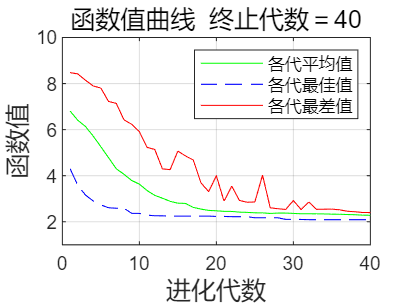

[r, c] = size(trace);
figure
plot((1:r)', trace(:, 1), 'g-', (1:r)', trace(:, 2), 'b--', (1:r)', trace(:, 3), 'r');
title(['函数值曲线  ' '终止代数＝' num2str(maxgen)], 'fontsize', 12);
xlabel('进化代数', 'fontsize', 12); ylabel('函数值', 'fontsize', 12);
legend('各代平均值','各代最佳值', '各代最差值');
ylim([1 10])
%xlim([1,size(trace,1)])
grid on

% 窗口显示
disp('函数值         变量');

函数值         变量


disp([bestfitness x]);

    2.0893    1.5087    1.5856    1.4889    1.6273    1.5739

